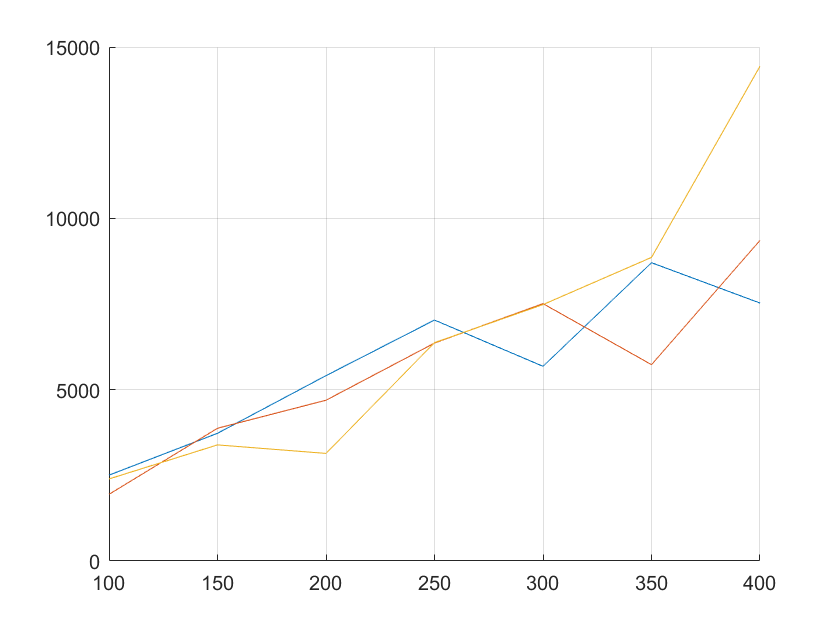

e = readtable("num_ue_vs_cost.csv");
e = removevars(e,"Var1");

% filter rows
a1 = e.alpha == 0.8;
a1 = e(a1,:);
a2 = e.alpha==1.6;
a2 = e(a2,:);
a3 = e.alpha==2.5;
a3 = e(a3,:);

x = a1.num_ue;
y1 = a1.cost;
y2 = a2.cost;
y3 = a3.cost;

hold on 
    plot(x,y1);
    plot(x,y2);
    plot(x,y3);
hold off